% 牽引物の慣性モーメント
syms xx yy zz real positive
syms a b c h v m

%平面の重心
x1 = [-1 -1 0 1 1 0];
y1 = [-1 1/2 1 1/2 -1/2 -1];
z1 = ones(1,6);
p = [x1;y1;z1];
G = [x;y;0.5];
rho = sum((p-G).^2)

rho =     2.0260    1.4683    1.3849    1.6734    1.5452    1.1285



polyin = polyshape(x1,y1);
[x,y] = centroid(polyin)

x = -0.0513

y = -0.0641

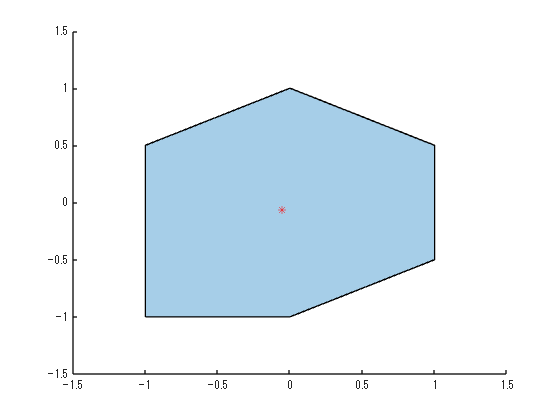

plot(polyin)
hold on
plot(x,y,'r*')
hold off

%z
Isqu = m*(a^2+b^2)/3;
V = 2*a*2*b*1 - (a*0.5*a*1)/2

$$V = 4\,a\,b-\frac{a^{2}}{4}$$

rho = m/V;
yMinRange = -(y1(3)-y1(4))*xx/x1(4) + y1(3);
f = xx^2+yy^2;
fy = int(f,yy,[yMinRange,y1(3)]);
Itri_z = int(fy,xx,[0,x1(4)])*rho;

Iz = Isqu*1 - 3*Itri + m*G(1:2)'*G(1:2);
Iz = double(subs(Iz,[a,b,m],[1,1,1.2]))

Iz = 0.4735


%y
xMinRange = (yy-h)*c/(v-h);
f = xx^2+zz^2;
fx = int(f,xx,[xMinRange,c]);
fxz = int(fx,zz,[-a,a]);
fxzy = int(fxz,yy,[v,h]);
Itri_y = fxzy*rho;

Iy = Isqu*2 - 3*Itri_y + m*G(2:3)'*G(2:3);
Iy = double(subs(Iy,[a,b,c,h,v,m],[1,0.5,1,1,0.5,1.2]))

Iy = 0.4478

%x
zMinRange = (h-v)*xx/c + v;
f = yy^2+zz^2;
fy = int(f,yy,[zMinRange,h]);
fyz = int(fy,zz,[-a,a]);
fyzx = int(fyz,xx,[0,c]);
Itri_x = fyzx*rho;

Ix = Isqu*2 - 3*Itri_x + m*[G(1);G(3)]'*[G(1);G(3)];
Ix = double(subs(Ix,[a,b,c,h,v,m],[1,0.5,1,1,0.5,1.2]))

Ix = 0.2317